# UC - Irvine Interview Task

Professor Dion Khodagholy

Nika Soltani Tehrani

March 2024

## Section 1) Initializations

clc
clear 
close all

load time.mat; % sampling rate is 1250Sample/s, 5s vector 
load data.mat; %% 11 channels of neural data, 1:6 from hippocampus, 7:11 from neocortex

## Section 2) Plotting Data

Plot the data as a function of time.

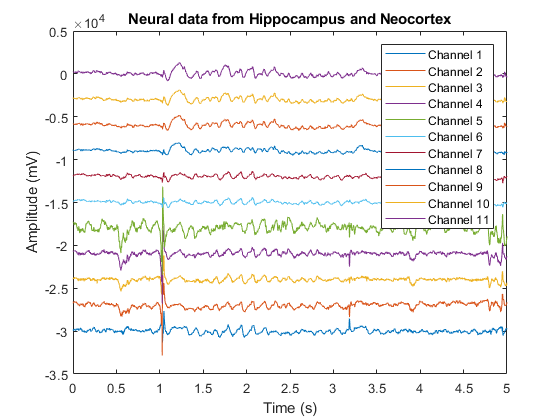

t = time;
figure(1);
plot(t,data);
legend('Channel 1','Channel 2','Channel 3','Channel 4','Channel 5','Channel 6','Channel 7','Channel 8','Channel 9','Channel 10','Channel 11'); % add a legend for the channels
xlabel('Time (s)');
xlim([0 5]); 
ylabel('Amplitude (mV)');
title('Neural data from Hippocampus and Neocortex');

## Section 3) Filtering Data

Filter all 6 channels using a 3rd order band pass butterworth filter (10 - 15 Hz)

Plot the results in a new figure 

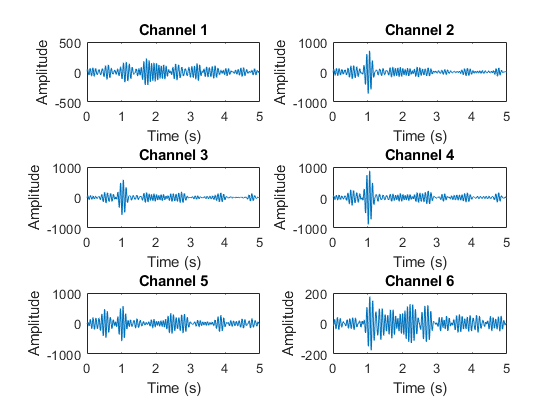

fs = 1250; % sampling frequency (1/T)
order = 3;
fc = [10 15];

[b,a] = butter(order, fc/ (fs/ 2),'bandpass');
filtered_hippocampus = zeros(size(data(1: 6,:)));

for i = 1:6
    filtered_hippocampus(i,:) = filtfilt(b, a, data(i, :));
end

figure(2); 

for i = 1:6
    subplot(3, 2, i);
    plot(time, filtered_hippocampus(i,:));
    xlabel('Time (s)');
    xlim([0 5]); 
    ylabel('Amplitude');
    title(['Channel ', num2str(i)]);
end

I wanted to see what does the signal look like in Neocortex too.

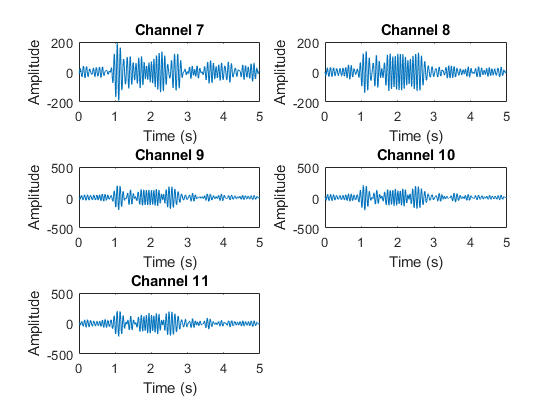


filtered_neocortex = zeros(size(data(7: 11,:)));

for i = 7:11
    filtered_neocortex(i,:) = filtfilt(b, a, data(i, :));
end

figure(4); 

for i = 1:5
    subplot(3, 2, i);
    plot(time, filtered_neocortex(i+6,:));
    xlabel('Time (s)');
    xlim([0 5]); 
    ylabel('Amplitude');
    title(['Channel ', num2str(i+6)]);
end

## Section 4) Extracting Power

Rectify the filtered data and extract the power either using a sliding window or low pass filter of the absolute value of the traces.

rectified_hippocampus = abs(filtered_hippocampus);
window = 500;
hippocampus_power = zeros(size(rectified_hippocampus, 1), size(rectified_hippocampus, 2));

for i = 1:size(rectified_hippocampus, 2)
    hippocampus_power(:,i) = movmean(rectified_hippocampus(:,i).^2, window); % calculating moving average
end

## Section 5) Thresholding

Define a threshold value using 4 x standard deviation of the signal 

Plot channel 3 and superimpose the thresold line (in dashed red)

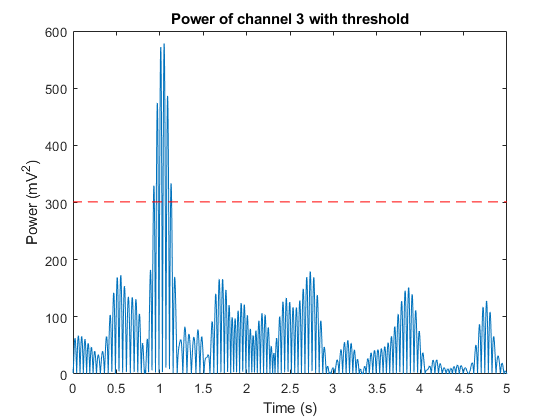

channel = 3;
threshold = 4 * std(rectified_hippocampus(channel, :));

figure(3);
plot(time, rectified_hippocampus(channel, :));
hold on;
plot(time, threshold * ones(size(time)),'r--');
hold off;
xlabel('Time (s)');
xlim([0 5]); 
ylabel('Power (mV^2)');
title(['Power of channel ' num2str(channel) ' with threshold']);